% 1. Define the ODE function with regularization
function dydx = bvpfcn(x, y)
    dydx = [
        y(2)/x - y(1)/x;
        (((2.592e-5) + (3.727e-7) * exp((1 + (5.673e-5) * (y(2)^2 + y(1)^2))^0.5) ...
        - (5.973e-6) - ((y(1) * y(2) * (3.727e-7) * exp((1 + (5.673e-5) * (y(2)^2 + y(1)^2))^0.5)) ...
        / ((1 + (5.673e-5) * (y(2)^2 + y(1)^2))^0.5))) * ((y(1) - y(2)) / x)) ...
        / (-6.133e-6 + 2.592e-5 + (3.727e-7) * exp((1 + (5.673e-5) * (y(2)^2 + y(1)^2))^0.5) ...
        + (3.727e-7) * y(2)^2 * exp((1 + (5.673e-5) * (y(2)^2 + y(1)^2))^0.5) ...
        / (1 + (5.673e-5) * (y(2)^2 + y(1)^2))^0.5)
    ];
end

% 2. Define the boundary condition function
function res = bcfcn(ya, yb)
    res = [ya(1) - 1;  % y(1) = 1 at x=0.01
           yb(2) - 0]; % y'(x) = 0 at x=1
end

% 3. Set options for the solver
opts = bvpset('RelTol', 1e-4, 'AbsTol', 1e-6, 'Stats', 'on');

% 4. Define the mesh and initial guess
xmesh = linspace(0.01, 1, 100); % Avoid x=0 to prevent singularity
solinit = bvpinit(xmesh, [1; 0]); % Initial guess: y(1)=1, y'(1)=0

% 5. Solve the BVP
sol4c = bvp4c(@bvpfcn, @bcfcn, solinit, opts);

The solution was obtained on a mesh of 70 points.
The maximum residual is  8.402e-05. 
There were 2847 calls to the ODE function. 
There were 32 calls to the BC function. 


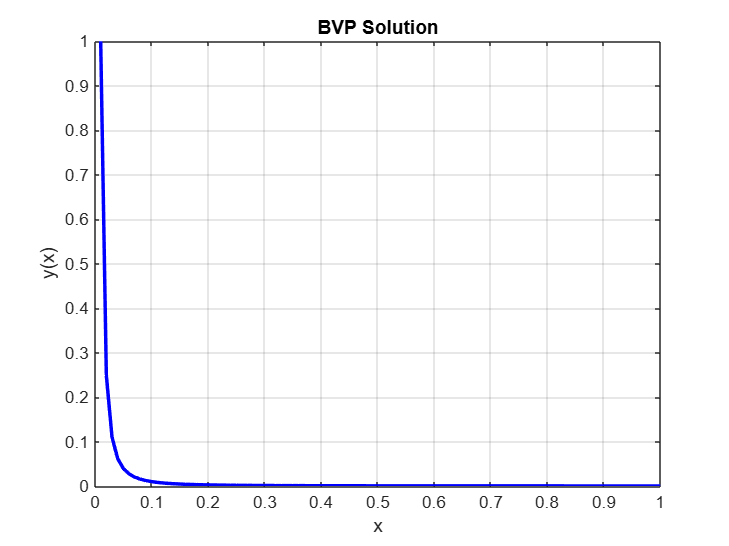


% 6. Process and plot the solution
x = linspace(sol4c.x(1), sol4c.x(end), 100); % Use solution's interval
y = deval(sol4c, x);

% 7. Plot results
figure;
plot(x, y(1, :), 'b-', 'LineWidth', 2);
xlabel('x');
ylabel('y(x)');
title('BVP Solution');
grid on;